opts = spreadsheetImportOptions("NumVariables", 7);

% Specify sheet
opts.Sheet = "DEC_10_SF1_GCTPH1.US01PR_with_a";

% Specify column names and types
opts.VariableNames = ["Population", "Housingunits", "AreainsquaremilesTotalarea", "AreainsquaremilesWaterarea", "AreainsquaremilesLandarea", "DensitypersquaremileoflandareaPopulation", "DensitypersquaremileoflandareaHousingunits"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Import the data
PopulationCensusData = table;
ranges = ["C3:I10", "C12:I53"];
for idx = 1:length(ranges)
    opts.DataRange = ranges(idx);
    tb = readtable("/Users/Cecilree/Documents/MATLAB/Population_Census_Data.xls", opts, "UseExcel", false);
    PopulationCensusData = [PopulationCensusData; tb] %#ok<AGROW>
end

PopulationCensusData = 8×7 table
    Population    Housingunits    AreainsquaremilesTotalarea    AreainsquaremilesWaterarea    AreainsquaremilesLandarea    DensitypersquaremileoflandareaPopulation    DensitypersquaremileoflandareaHousingunits
    __________    ____________    __________________________    __________________________    _________________________    ________________________________________    __________________________________________

    4.7797e+06     2.1719e+06                  52420                      1774.7                          50645                              94.4                                         42.9                   
    7.1023e+05     3.0697e+05             6.6538e+05                       94743                  

PopulationCensusData = 50×7 table
    Population    Housingunits    AreainsquaremilesTotalarea    AreainsquaremilesWaterarea    AreainsquaremilesLandarea    DensitypersquaremileoflandareaPopulation    DensitypersquaremileoflandareaHousingunits
    __________    ____________    __________________________    __________________________    _________________________    ________________________________________    __________________________________________

    4.7797e+06     2.1719e+06                  52420                      1774.7                          50645                              94.4                                         42.9                   
    7.1023e+05     3.0697e+05             6.6538e+05                       94743                 


clear idx opts ranges tb

PopCensusData = table2array(PopulationCensusData);

Means = mean(PopCensusData);
NewMeans = {Means(1),Means(2),Means(3),Means(4),Means(5),Means(6),Means(7)}

NewMeans = 1×7 cell array
    {[6.1629e+06]}    {[2.6282e+06]}    {[7.5933e+04]}    {[5.2966e+03]}    {[7.0637e+04]}    {[194.9620]}    {[83.8560]}



STDS = std(PopCensusData);
NewSTDs = {STDS(1),STDS(2),STDS(3),STDS(4),STDS(5),STDS(6),STDS(7)}

NewSTDs = 1×7 cell array
    {[6.8482e+06]}    {[2.7185e+06]}    {[9.7327e+04]}    {[1.4256e+04]}    {[8.5816e+04]}    {[261.0915]}    {[109.9146]}



Medians = median(PopCensusData);
NewMedians = {Medians(1),Medians(2),Medians(3),Medians(4),Medians(5),Medians(6),Medians(7)}

NewMedians = 1×7 cell array
    {[4.4364e+06]}    {[1.9461e+06]}    {[5.7093e+04]}    {[1.5012e+03]}    {[5.3891e+04]}    {[98.7500]}    {[43.1500]}



PopCData = timeseries(PopCensusData);
IQRS = iqr(PopCData);
NewIQRS = {IQRS(1),IQRS(2),IQRS(3),IQRS(4),IQRS(5),IQRS(6),IQRS(7)}

NewIQRS = 1×7 cell array
    {[4898199]}    {[2088884]}    {[4.8477e+04]}    {[3.8080e+03]}    {[4.5933e+04]}    {[168.7000]}    {[66.4000]}


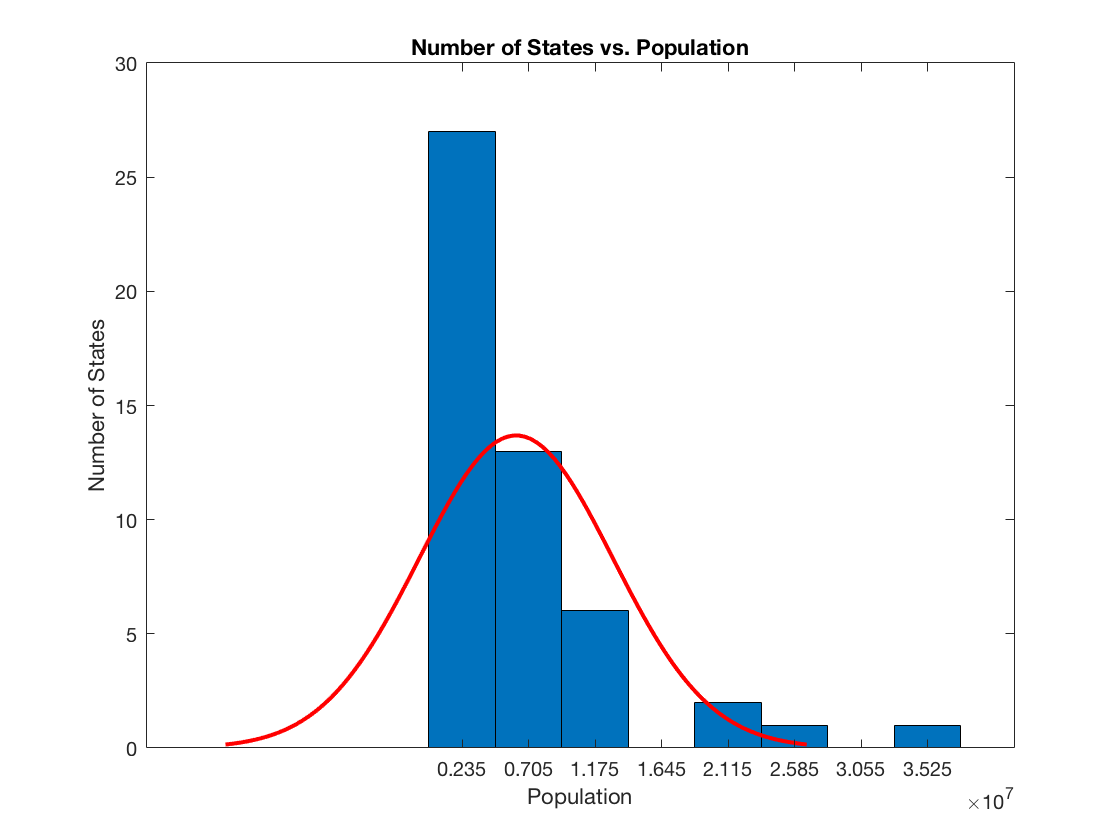


population = PopCensusData(1:50,1);
histfit(population)
xlabel('Population')
ylabel('Number of States')
title('Number of States vs. Population')

PopMean = Means(1)

PopMean = 6.1629e+06

PopSTD = STDS(1)

PopSTD = 6.8482e+06

PopMedian = Medians(1)

PopMedian = 4.4364e+06

PopIQR = IQRS(1)

PopIQR = 4898199

Pop5NumSum = prctile(population,[0 25 50 75 100])

Pop5NumSum = 	1.0e+07 *

    0.0564    0.1826    0.4436    0.6725    3.7254


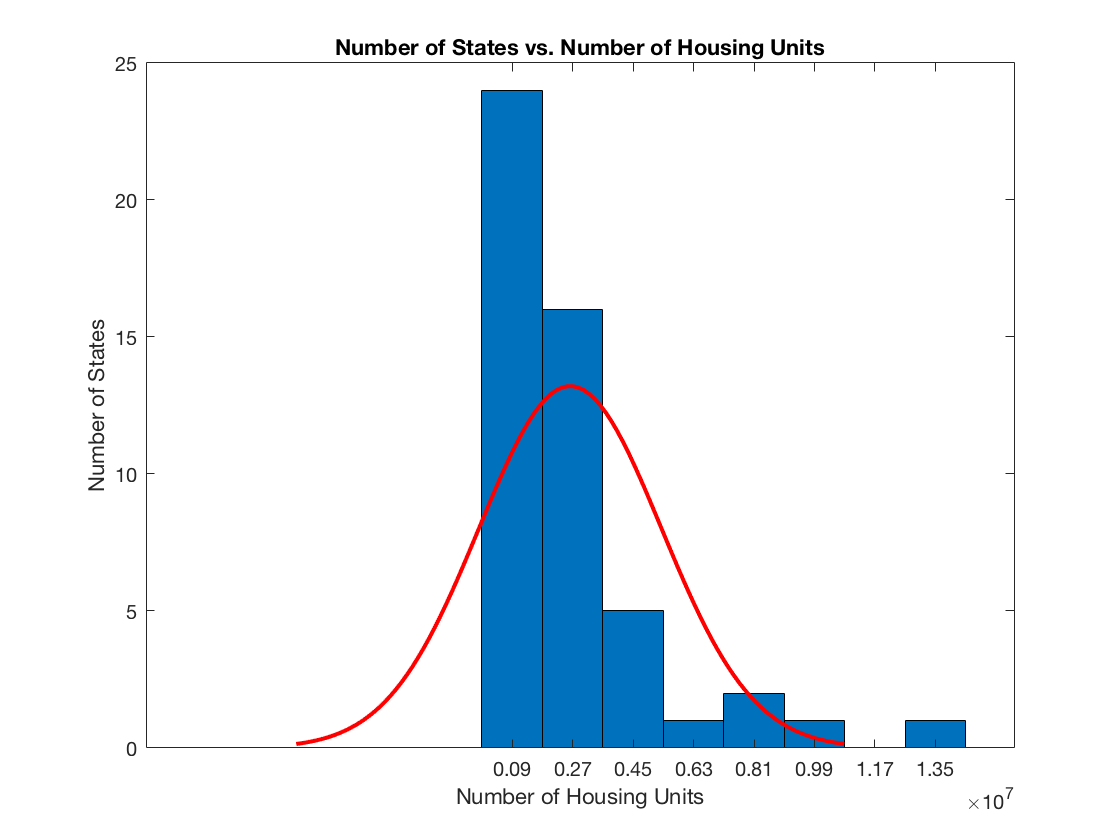


housing = PopCensusData(1:50,2);
histfit(housing)
xlabel('Number of Housing Units')
ylabel('Number of States')
title('Number of States vs. Number of Housing Units')

HousingMean = Means(2)

HousingMean = 2.6282e+06

HousingSTD = STDS(2)

HousingSTD = 2.7185e+06

HousingMedian = Medians(2)

HousingMedian = 1.9461e+06

HousingIQR = IQRS(2)

HousingIQR = 2088884

Housing5NumSum = prctile(housing,[0 25 50 75 100])

Housing5NumSum = 	1.0e+07 *

    0.0262    0.0797    0.1946    0.2886    1.3680


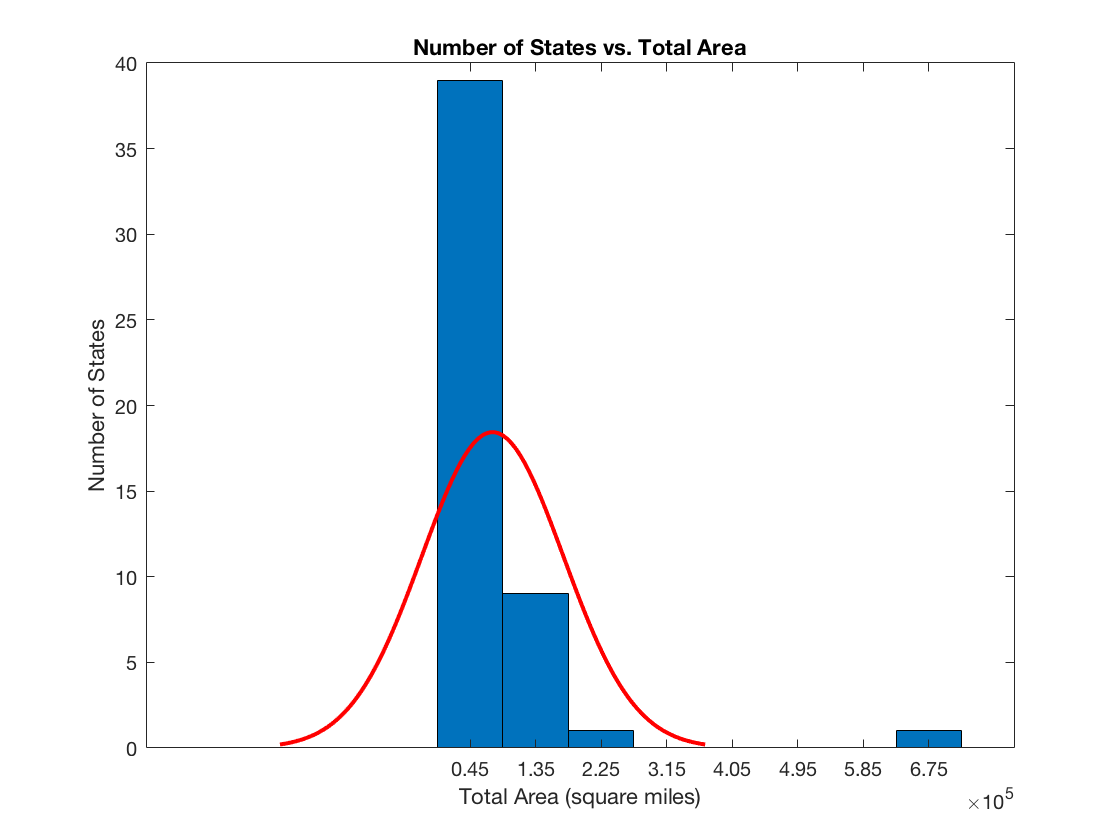


area = PopCensusData(1:50,3);
histfit(area)
xlabel('Total Area (square miles)')
ylabel('Number of States')
title('Number of States vs. Total Area')

AreaMean = Means(3)

AreaMean = 7.5933e+04

AreaSTD = STDS(3)

AreaSTD = 9.7327e+04

AreaMedian = Medians(3)

AreaMedian = 5.7093e+04

AreaIQR = IQRS(3)

AreaIQR = 4.8477e+04

Area5NumSum = prctile(area,[0 25 50 75 100])

Area5NumSum = 	1.0e+05 *

    0.0154    0.3642    0.5709    0.8490    6.6538


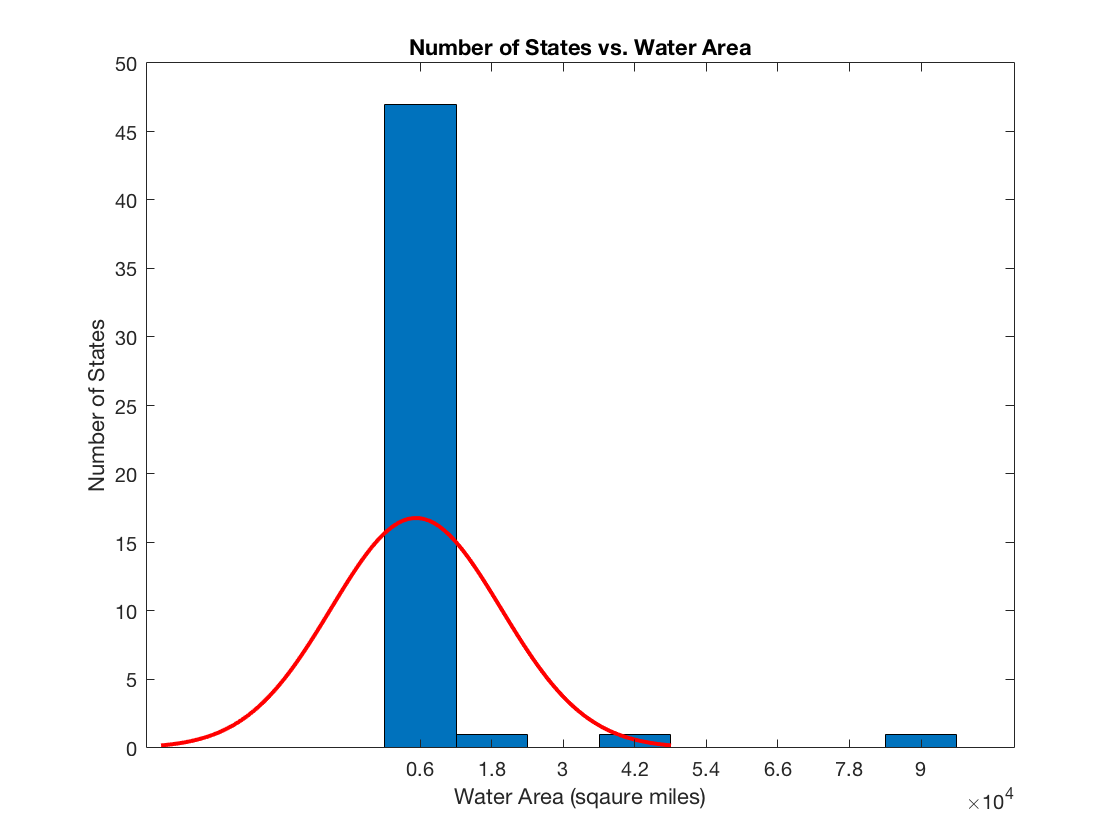


WaterArea = PopCensusData(1:50,4);
histfit(WaterArea)
xlabel('Water Area (sqaure miles)')
ylabel('Number of States')
title('Number of States vs. Water Area')

WaterAreaMean = Means(4)

WaterAreaMean = 5.2966e+03

WaterAreaSTD = STDS(4)

WaterAreaSTD = 1.4256e+04

WaterAreaMedian = Medians(4)

WaterAreaMedian = 1.5012e+03

WaterAreaIQR = IQRS(4)

WaterAreaIQR = 3.8080e+03

WaterArea5NumSum = prctile(WaterArea,[0 25 50 75 100])

WaterArea5NumSum = 	1.0e+04 *

    0.0192    0.0701    0.1501    0.4509    9.4743


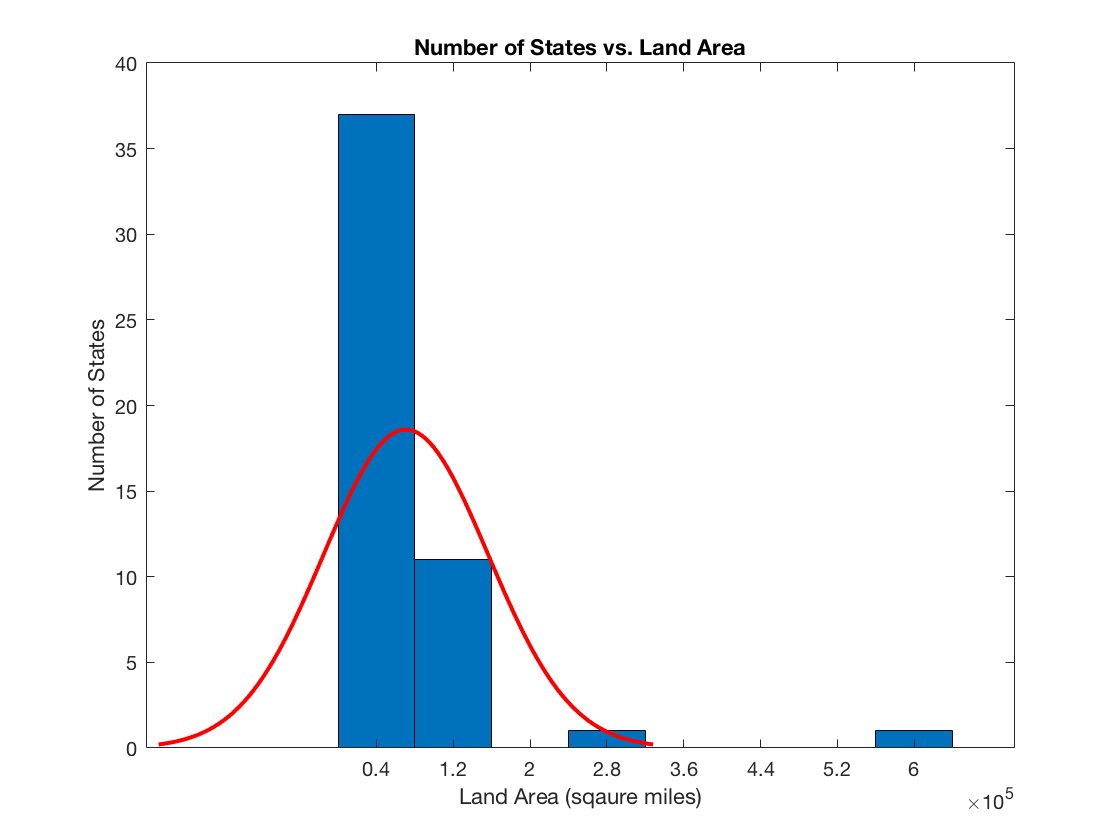


LandArea = PopCensusData(1:50,5);
histfit(LandArea)
xlabel('Land Area (sqaure miles)')
ylabel('Number of States')
title('Number of States vs. Land Area')

LandAreaMean = Means(5)

LandAreaMean = 7.0637e+04

LandAreaSTD = STDS(5)

LandAreaSTD = 8.5816e+04

LandAreaMedian = Medians(5)

LandAreaMedian = 5.3891e+04

LandAreaIQR = IQRS(5)

LandAreaIQR = 4.5933e+04

LandArea5NumSum = prctile(LandArea,[0 25 50 75 100])

LandArea5NumSum = 	1.0e+05 *

    0.0103    0.3583    0.5389    0.8176    5.7064


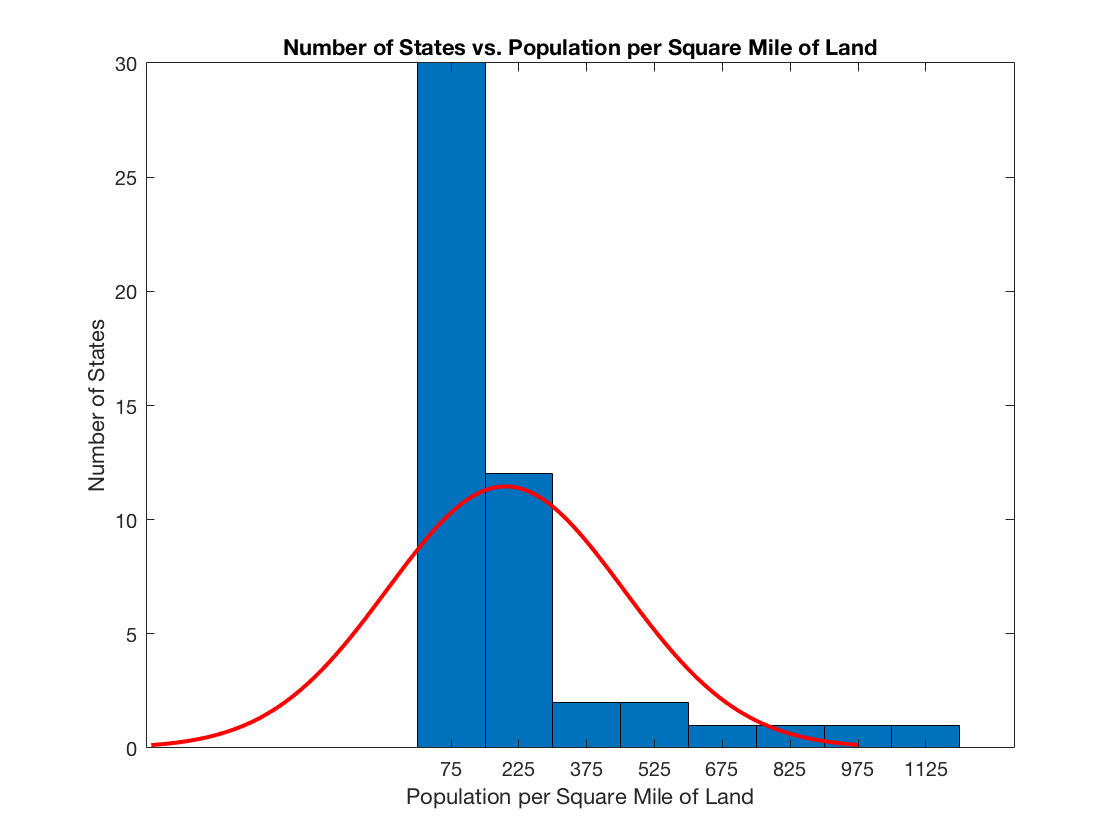


PopPerSqMile = PopCensusData(1:50,6);
histfit(PopPerSqMile)
xlabel('Population per Square Mile of Land')
ylabel('Number of States')
title('Number of States vs. Population per Square Mile of Land')

PopPerSqMileMean = Means(6)

PopPerSqMileMean = 194.9620

PopPerSqMileSTD = STDS(6)

PopPerSqMileSTD = 261.0915

PopPerSqMileMedian = Medians(6)

PopPerSqMileMedian = 98.7500

PopPerSqMileIQR = IQRS(6)

PopPerSqMileIQR = 168.7000

PopPerSqMile5NumSum = prctile(PopPerSqMile,[0 25 50 75 100])

PopPerSqMile5NumSum = 	1.0e+03 *

    0.0012    0.0431    0.0988    0.2118    1.1955



HousingPerSqMile = PopCensusData(1:50,7);
histfit(HousingPerSqMile)
xlabel('Housing Units per Square Mile of Land')
ylabel('Number of States')
title('Number of States vs. Housing Units per Square Mile of Land')
HousingPerSqMileMean = Means(7)

HousingPerSqMileMean = 83.8560

HousingPerSqMileSTD = STDS(7)

HousingPerSqMileSTD = 109.9146

HousingPerSqMileMedian = Medians(7)

HousingPerSqMileMedian = 43.1500

HousingPerSqMileIQR = IQRS(7)

HousingPerSqMileIQR = 66.4000

HousingPerSqMile5NumSum = prctile(HousingPerSqMile,[0 25 50 75 100])

HousingPerSqMile5NumSum =     0.5000   21.4000   43.1500   87.8000  483.2000


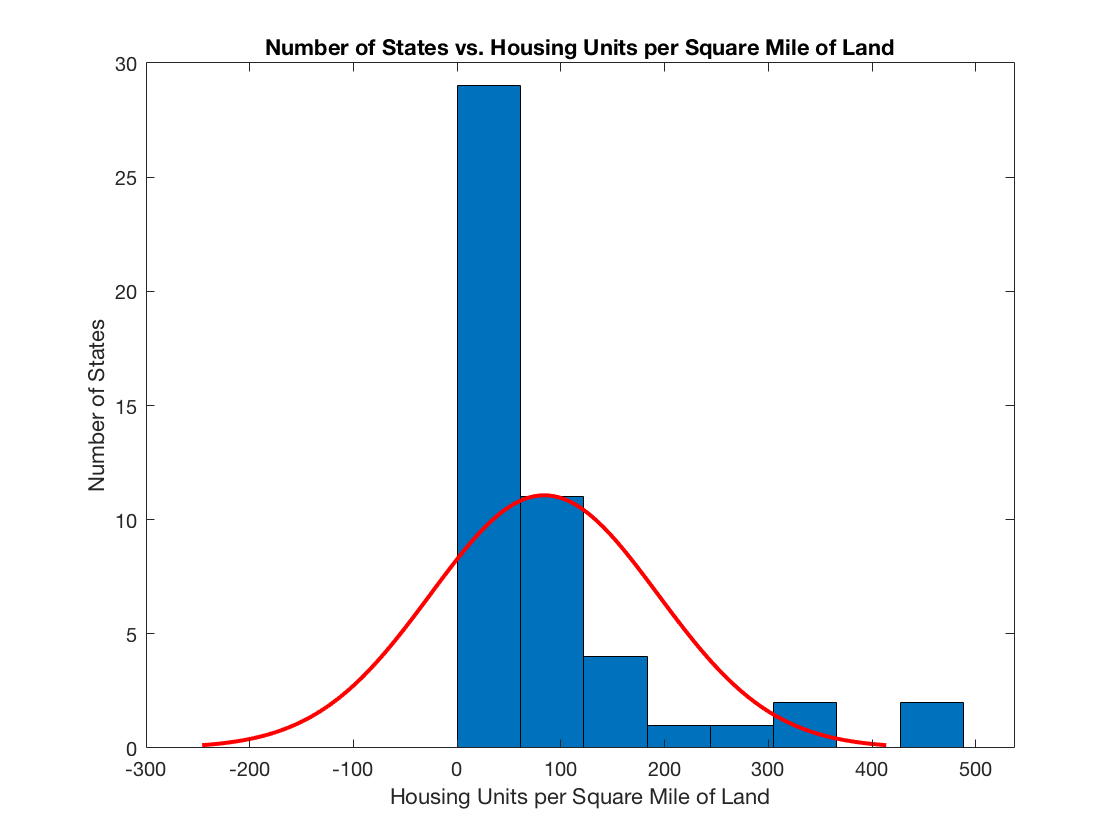

hold off


zscores = normalize(PopulationCensusData)

zscores = 50×7 table
    Population    Housingunits    AreainsquaremilesTotalarea    AreainsquaremilesWaterarea    AreainsquaremilesLandarea    DensitypersquaremileoflandareaPopulation    DensitypersquaremileoflandareaHousingunits
    __________    ____________    __________________________    __________________________    _________________________    ________________________________________    __________________________________________

     -0.20197       -0.16785               -0.24159                      -0.24704                     -0.23296                             -0.38516                                     -0.37262                 
     -0.79621       -0.85386                 6.0564                        6.2743                       5.8265

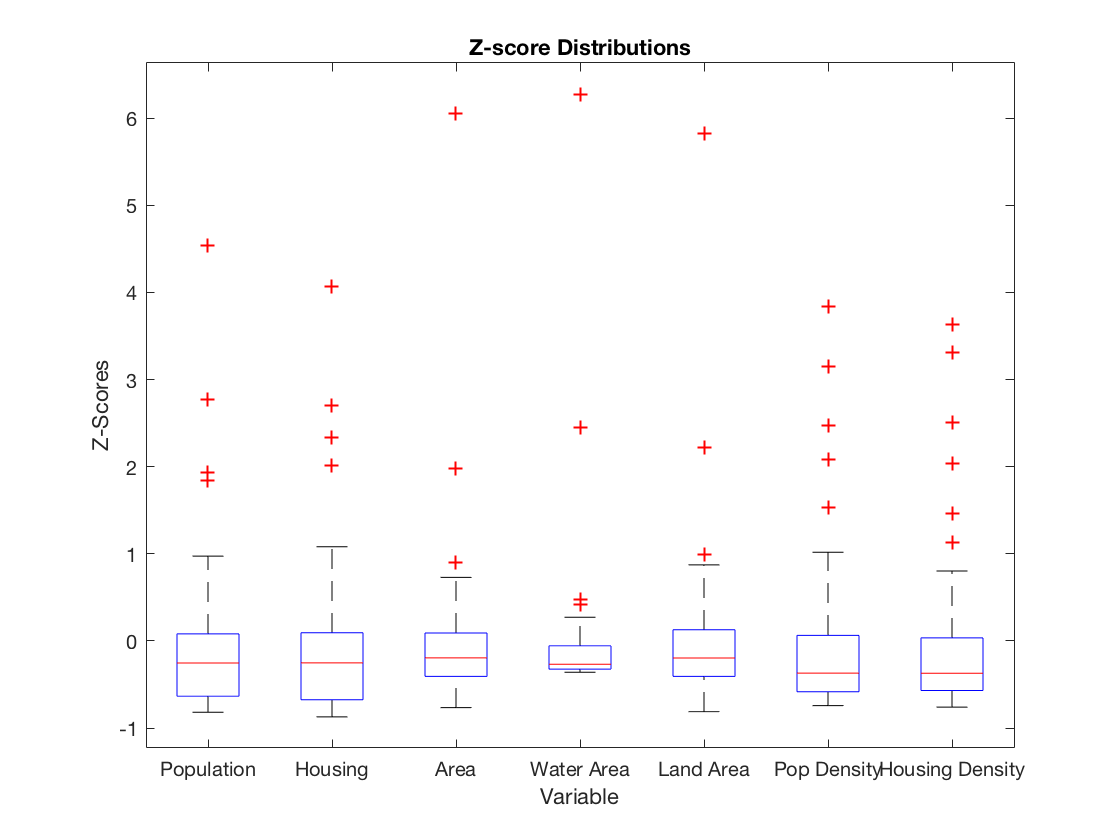

zarray = table2array(zscores);
ZP = zarray(1:50,1);
ZH = zarray(1:50,2);
ZA = zarray(1:50,3);
ZWA = zarray(1:50,4);
ZLA = zarray(1:50,5);
ZDP = zarray(1:50,6);
ZDH = zarray(1:50,7);
boxplot([ZP,ZH,ZA,ZWA,ZLA,ZDP,ZDH],'Labels',{'Population','Housing','Area','Water Area','Land Area','Pop Density','Housing Density'})
title('Z-score Distributions')
xlabel('Variable')
ylabel('Z-Scores')

hold off


m1 = population\PopPerSqMile

m1 = 1.7904e-05

y1 = population*m1;
X1 = [ones(length(population),1) population];
B1 = X1\PopPerSqMile

B1 =   154.5484
    0.0000


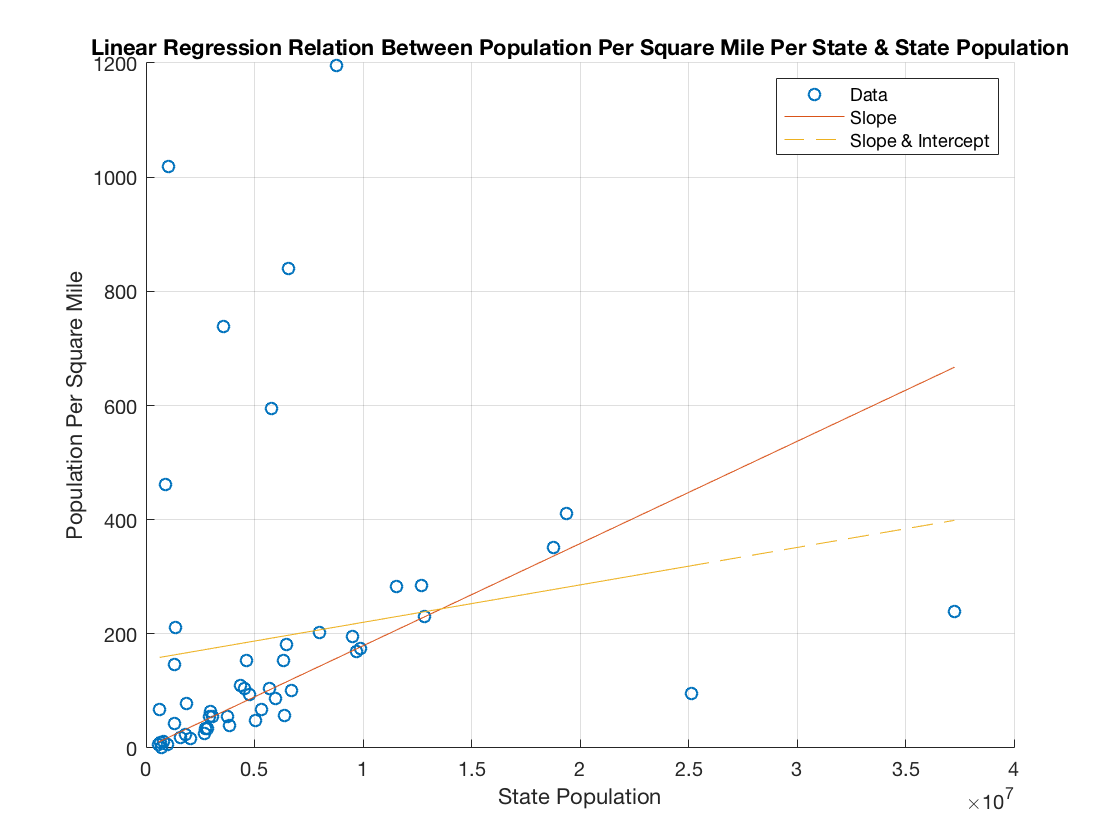

scatter(population,PopPerSqMile)
hold on
plot(population,y1)
grid on
y01 = X1*B1;
plot(population,y01,'--')
xlabel('State Population')
ylabel('Population Per Square Mile')
title('Linear Regression Relation Between Population Per Square Mile Per State & State Population')
legend('Data','Slope','Slope & Intercept')
hold off


Rsq1 = 1 - sum((PopPerSqMile - y01).^2)/sum((PopPerSqMile - PopPerSqMileMean).^2)

Rsq1 = 0.0296

r1 = sqrt(Rsq1)

r1 = 0.1720

if 0 == r1
        disp('There is no correlation between Population Per Sqaure Mile and State Population')
elseif 0.0001 <= r1 < 0.20
        disp('There is a very weak correlation between Population Per Sqaure Mile and State Population')
elseif 0.20 <= r1 < 0.40
        disp('There is a weak correlation between Population Per Sqaure Mile and State Population')
elseif 0.40 <= r1 < 0.60
        disp('There is a moderate correlation between Population Per Sqaure Mile and State Population')
elseif 0.60 <= r1 < 0.80
        disp('There is a strong correlation between Population Per Sqaure Mile and State Population')
elseif 0.80 <= r1 <= 1
    disp('There is a very strong correlation between Population Per Sqaure Mile and State Population')
end

There is a weak correlation between Population Per Sqaure Mile and State Population



m2 = housing\HousingPerSqMile

m2 = 1.9056e-05

y2 = housing*m2;
X2 = [ones(length(housing),1) housing];
B2 = X2\HousingPerSqMile

B2 =    65.9861
    0.0000


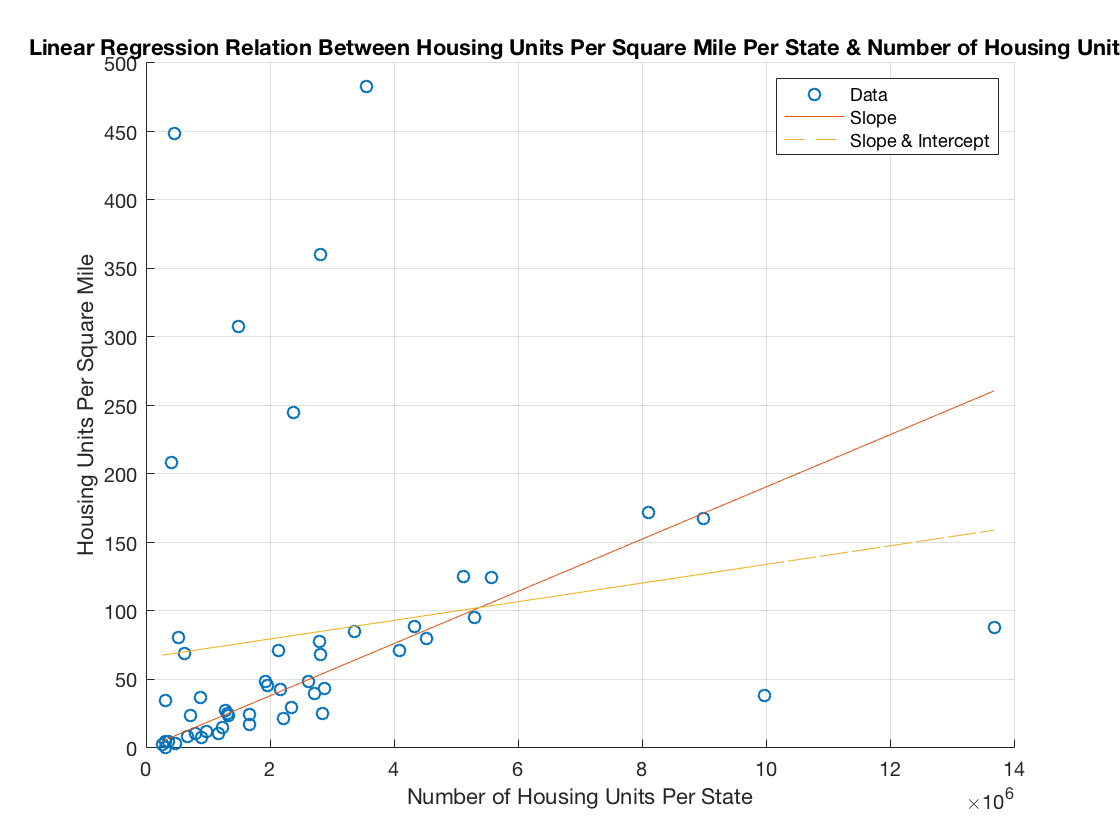

scatter(housing,HousingPerSqMile)
hold on
plot(housing,y2)
grid on
y02 = X2*B2;
plot(housing,y02,'--')
xlabel('Number of Housing Units Per State')
ylabel('Housing Units Per Square Mile')
title('Linear Regression Relation Between Housing Units Per Square Mile Per State & Number of Housing Units')
legend('Data','Slope','Slope & Intercept')
hold off


Rsq2 = 1 - sum((HousingPerSqMile - y02).^2)/sum((HousingPerSqMile - HousingPerSqMileMean).^2)

Rsq2 = 0.0283

r2 = sqrt(Rsq2)

r2 = 0.1682

if 0 == r2
    disp('There is no correlation between Housing Per Sqaure Mile and Number of Housing Units')
elseif 0.0001 <= r2 < 0.20
        disp('There is a very weak correlation between Housing Per Sqaure Mile and Number of Housing Units')
elseif 0.20 <= r2 < 0.40
        disp('There is a weak correlation between Housing Per Sqaure Mile and Number of Housing Units')
elseif 0.40 <= r2 < 0.60
        disp('There is a moderate correlation between Housing Per Sqaure Mile and Number of Housing Units')
elseif 0.60 <= r2 < 0.80
        disp('There is a strong correlation between Housing Per Sqaure Mile and Number of Housing Units')
elseif 0.80 <= r2 <= 1
        disp('There is a very strong correlation between Housing Per Sqaure Mile and Number of Housing Units')
end

There is a weak correlation between Housing Per Sqaure Mile and Number of Housing Units



m3 = LandArea\HousingPerSqMile

m3 = 2.1529e-04

y3 = LandArea*m3;
X3 = [ones(length(LandArea),1) LandArea];
B3 = X3\HousingPerSqMile

B3 =   116.1094
   -0.0005


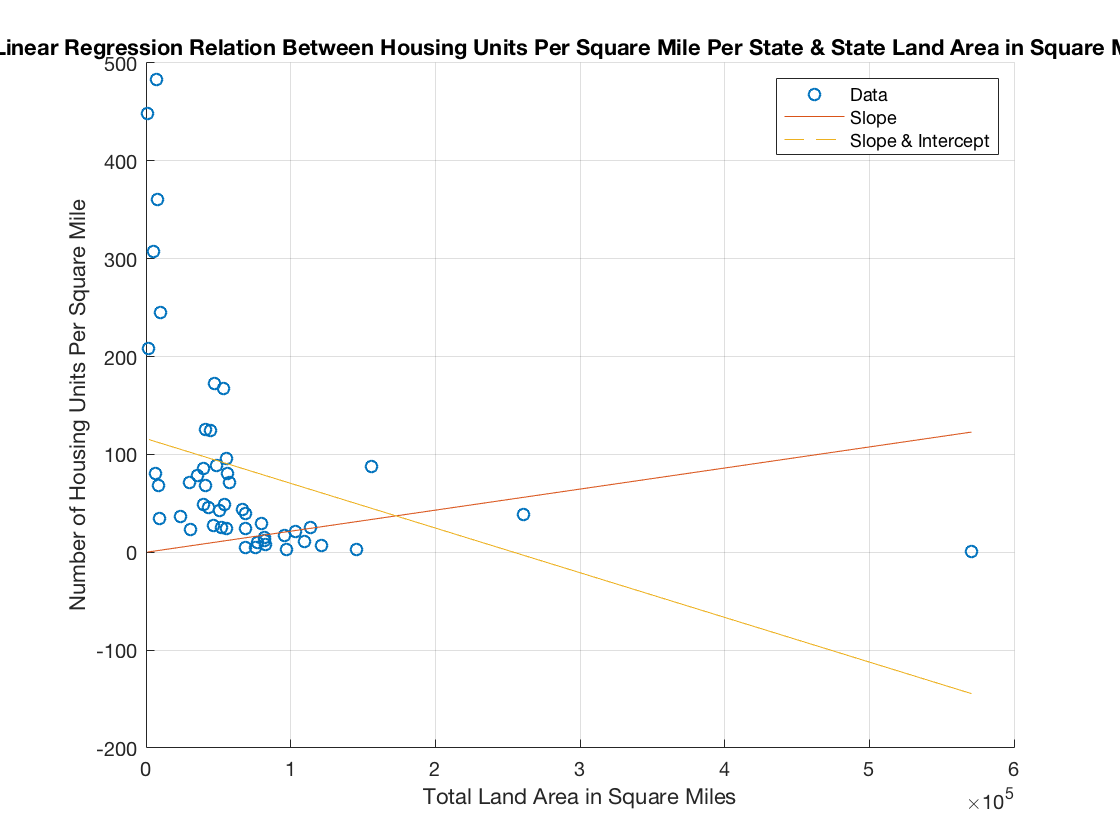

scatter(LandArea,HousingPerSqMile)
hold on
plot(LandArea,y3)
grid on
y03 = X3*B3;
plot(LandArea,y03,'--')
xlabel('Total Land Area in Square Miles')
ylabel('Number of Housing Units Per Square Mile')
title('Linear Regression Relation Between Housing Units Per Square Mile Per State & State Land Area in Square Miles')
legend('Data','Slope','Slope & Intercept')
hold off


Rsq3 = 1 - sum((HousingPerSqMile - y03).^2)/sum((HousingPerSqMile - HousingPerSqMileMean).^2)

Rsq3 = 0.1271

r3 = sqrt(Rsq3)

r3 = 0.3565

if 0 == r3
    disp('There is no correlation between the Number of Housing Units Per Sqaure Mile and Land Area in Square Miles')
elseif 0.0001 <= r3 < 0.20
        disp('There is a very weak correlation between the Number of Housing Units Per Sqaure Mile and Land Area in Square Miles')
elseif 0.20 <= r3 < 0.40
        disp('There is a weak correlation between the Number of Housing Units Per Sqaure Mile and Land Area in Square Miles')
elseif 0.40 <= r3 < 0.60
        disp('There is a moderate correlation between the Number of Housing Units Per Sqaure Mile and Land Area in Square Miles')
elseif 0.60 <= r3 < 0.80
        disp('There is a strong correlation between the Number of Housing Units Per Sqaure Mile and Land Area in Square Miles')
elseif 0.80 <= r3 <= 1
        disp('There is a very strong correlation between the Number of Housing Units Per Sqaure Mile and Land Area in Square Miles')
end

There is a moderate correlation between the Number of Housing Units Per Sqaure Mile and Land Area in Square Miles



m4 = population\housing

m4 = 0.4089

y4 = population*m4;
X4 = [ones(length(population),1) population];
B4 = X4\housing

B4 = 	1.0e+05 *

    1.9738
    0.0000


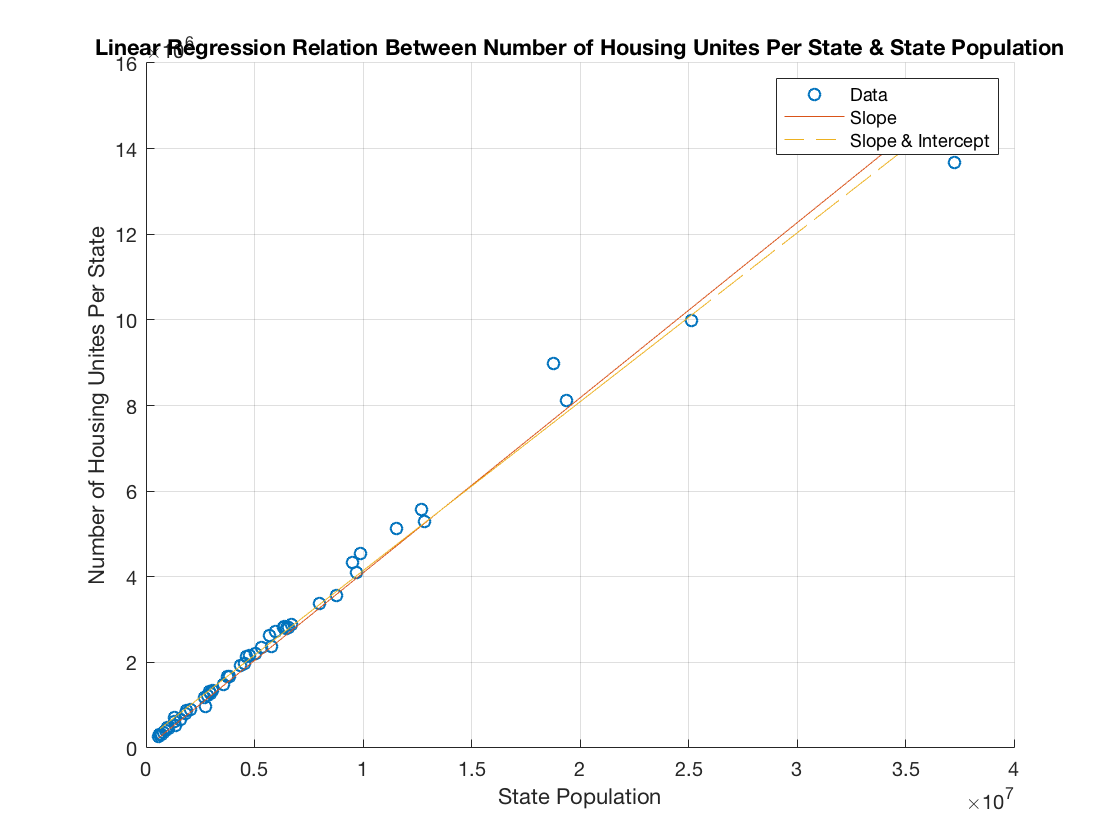

scatter(population,housing)
hold on
plot(population,y4)
grid on
y04 = X4*B4;
plot(population,y04,'--')
xlabel('State Population')
ylabel('Number of Housing Unites Per State')
title('Linear Regression Relation Between Number of Housing Unites Per State & State Population')
legend('Data','Slope','Slope & Intercept')


Rsq4 = 1 - sum((housing - y04).^2)/sum((housing - HousingMean).^2)

Rsq4 = 0.9873

r4 = sqrt(Rsq4)

r4 = 0.9936

if 0 == r4
    disp('There is no correlation between Number of Housing Units and Population')
elseif 0.0001 <= r4 < 0.20
        disp('There is a very weak correlation between Number of Housing Units and Population')
elseif 0.20 <= r4 < 0.40
        disp('There is a weak correlation between Number of Housing Units and Population')
elseif 0.40 <= r4 < 0.60
        disp('There is a moderate correlation between Number of Housing Units and Population')
elseif 0.60 <= r4 < 0.80
        disp('There is a strong correlation between Number of Housing Units and Population')
elseif 0.80 <= r4 <= 1
        disp('There is a very strong correlation between Number of Housing Units and Population')
end

There is a very strong correlation between Number of Housing Units and Population



disp('This Concludes the 2010 Population Census Data Analysis by Reed Cecil!')

This Concludes the 2010 Population Census Data Analysis by Reed Cecil!
